# Create and Train a Deep Learning Model

Script for creating and training a deep learning network with the following properties:

Run this script to create the network layers, import training and validation data, and train the network. The network layers are stored in the workspace variable `layers`. The trained network is stored in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 23-Jul-2020 18:57:26

## Load Initial Parameters

Load parameters for network initialization. For transfer learning, the network initialization parameters are the parameters of the initial pretrained network.

trainingSetup = load("C:\Users\pablo\Documents\UNIVERSIDAD\TFG_Neural_Network\MatLab\MisCosas\MatLab-TFG-Neural-Network\LineaBola2\trainingSetup_2020_07_23__18_57_23.mat");

## Import Data

Import training and validation data.

imdsTrain = imageDatastore("C:\Users\pablo\Documents\UNIVERSIDAD\TFG_Neural_Network\MatLab\MisCosas\MatLab-TFG-Neural-Network\LineaBola2\imgLineaBolaDobleC","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.7);

## Augmentation Settings

imageAugmenter = imageDataAugmenter(...
    "RandXReflection",true,...
    "RandYReflection",true);

% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore([100 100 1],imdsTrain,"DataAugmentation",imageAugmenter);
augimdsValidation = augmentedImageDatastore([100 100 1],imdsValidation);

## Set Training Options

Specify options to use when training.

opts = trainingOptions("sgdm",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",0.01,...
    "MaxEpochs",60,...
    "Shuffle","every-epoch",...
    "ValidationFrequency",10,...
    "Plots","training-progress",...
    "ValidationData",augimdsValidation);

## Create Array of Layers

layers = [
    imageInputLayer([100 100 1],"Name","imageinput")
    convolution2dLayer([3 3],8,"Name","conv_1","Padding","same")
    maxPooling2dLayer([2 2],"Name","maxpool_1","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    convolution2dLayer([3 3],16,"Name","conv_2","Padding","same")
    maxPooling2dLayer([2 2],"Name","maxpool_2","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")
    convolution2dLayer([3 3],32,"Name","conv_3","Padding","same")
    maxPooling2dLayer([2 2],"Name","maxpool_3","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")
    convolution2dLayer([3 3],64,"Name","conv_4","Padding","same")
    maxPooling2dLayer([2 2],"Name","maxpool_4","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_4")
    reluLayer("Name","relu_4")
    fullyConnectedLayer(3,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Train Network

Train the network using the specified options and training data.

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:02 |       47.66% |       43.33% |       1.1001 |       1.0947 |          0.0100 |


|      10 |          10 |       00:00:10 |       79.69% |       77.78% |       0.4398 |       0.5860 |          0.0100 |


|      20 |          20 |       00:00:20 |       93.75% |       90.00% |       0.2298 |       0.3007 |          0.0100 |


|      30 |          30 |       00:00:30 |       99.22% |       92.22% |       0.0640 |       0.2123 |          0.0100 |


|      40 |          40 |       00:00:39 |       99.22% |       94.44% |       0.0454 |       0.1568 |          0.0100 |


|      50 |          50 |       00:00:49 |      100.00% |       94.44% |       0.0212 |       0.1410 |          0.0100 |


|      60 |          60 |       00:01:02 |      100.00% |       93.33% |       0.0174 |       0.1386 |          0.0100 |


|======================================================================================================================|


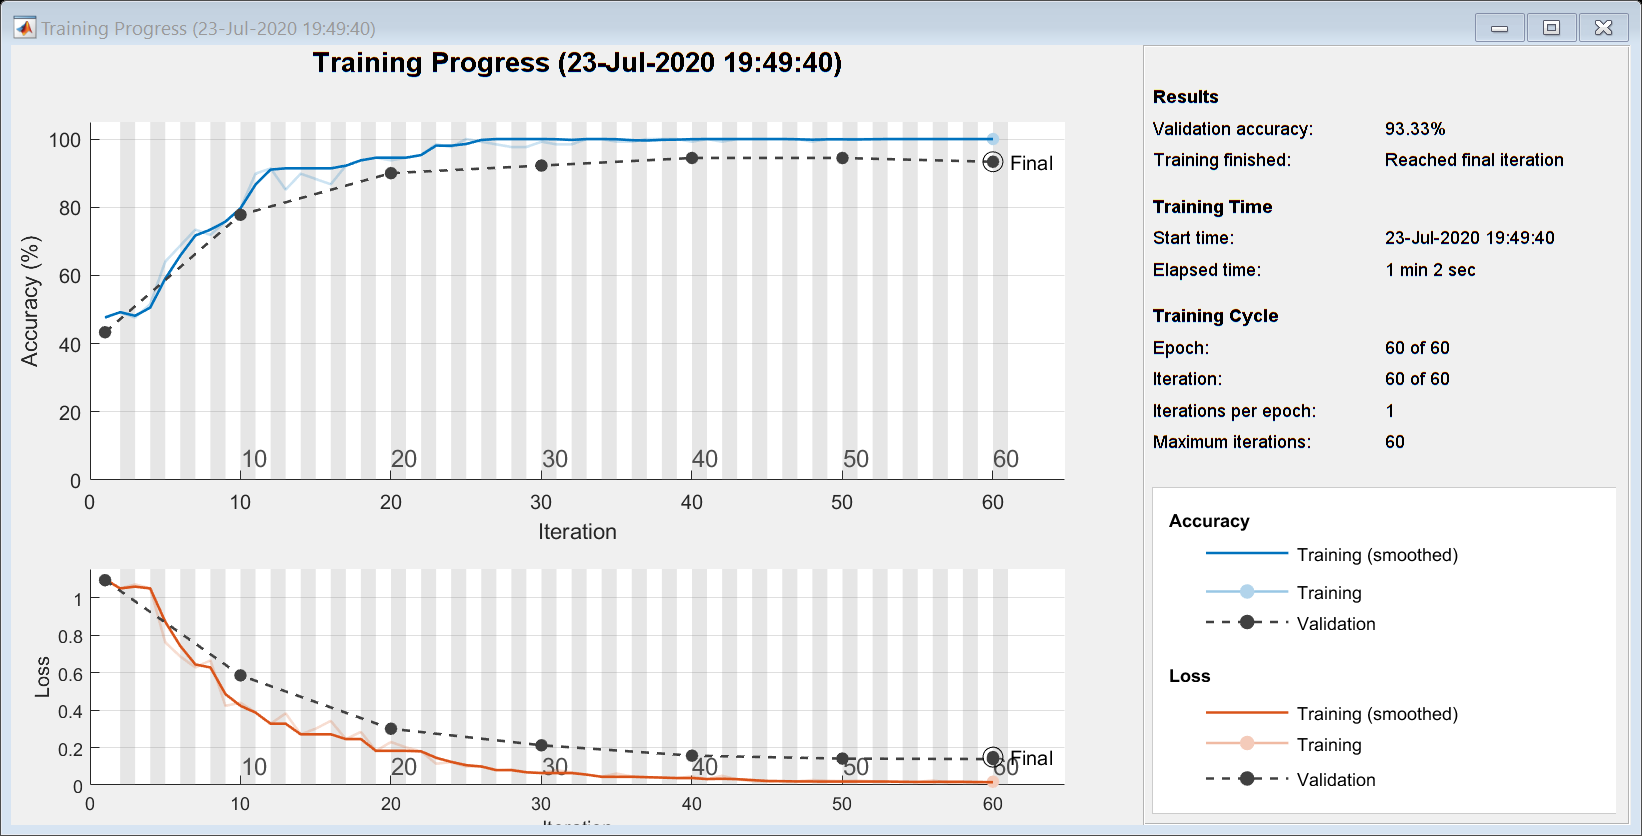

[net, traininfo] = trainNetwork(augimdsTrain,layers,opts);

## Save Results

save resultados2 net imdsTrain imdsValidation layers opts